**Task 1:**

*1.a.*

Determine the probability of the student to select the right answer. Answer: 70%

Studied a percentage 𝑝 (with 0% ≤ 𝑝 ≤ 100%)

E = responde corretamente

F1 = sabe a resposta   -->   P(F1) = p (oq o aluno estudou)

F2 = não sabe a resposta   -->   P(F2) = ~p (oq o aluno não estudou)

P (E|F1) = 1

P (E|F2) = 1/n

P(E) = P(E|F1) * P(F1) + P(E|F2) * P(F2) 

p = 0.6;
n = 4;

P_right = 1 * p + 1/n * 0.4;

disp(P_right);

    0.7000



*1.b.*

Determine the probability of the student to known the answer when he selects the right answer. Answer: 92.1%

P(F1|E) = P(EF1) / P(E) = **(P(E|F1) P(F1)) / P(E)**

p = 0.7;
n = 5;

P_F1 = p;

P_E = 1 * p + 1/n * 0.3;
P_E_F1 = 1;

P_F1_E = (P_E_F1 * P_F1) / P_E

P_F1_E = 0.9211

*1.c.*

Draw a plot with the same look as the plot below with the probability of the student to select the right answer as a function of the probability 𝑝 (consider the number of multiple answers 𝑛 = 3, 4 and 5). What do you conclude from these results? Answer:

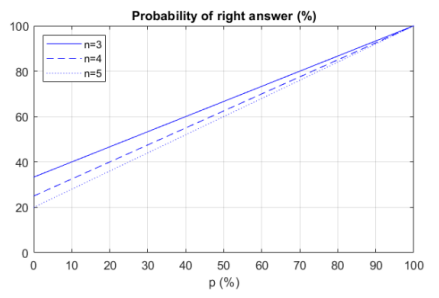

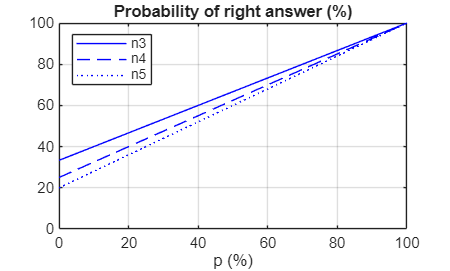

p = linspace(0, 1, 100);

n3 = 3;
n4 = 4;
n5 = 5;

y = p + (1-p) * (1/n3);
y1 = p + (1-p) * (1/n4); 
y2 = p + (1-p) * (1/n5);

plot(p*100,y*100,'b-')
hold on
plot(p*100,y1*100, 'b--')
hold on
plot(p*100,y2*100,'b:')
hold off

xlabel('p (%)');
title('Probability of right answer (%)');
legend('n3', 'n4', 'n5', 'Location', 'northwest');
grid on
ylim([0 100])

*1.d.*

Draw a plot with the same look as the plot below with the probability of the student to know the answer when he selects the right answer as a function of the probability 𝑝 (consider 𝑛 = 3, 4 and 5). What do you conclude from these results? Answer:

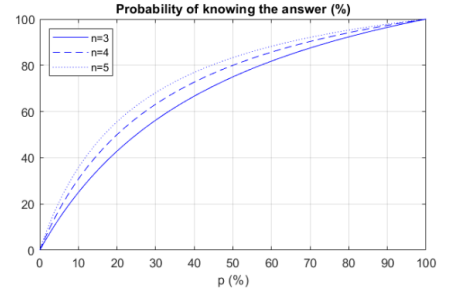

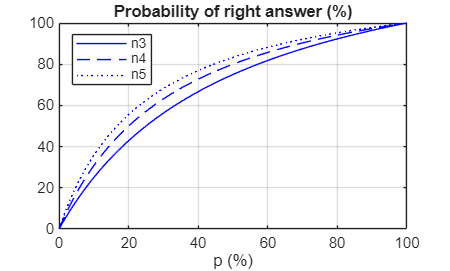

p = linspace(0, 1, 100);

n3 = 3;
n4 = 4;
n5 = 5;

y = 1 * p + 1/n3 * (1 - p);
y1 = 1 * p + 1/n4 * (1 - p);
y2 = 1 * p + 1/n5 * (1 - p);

P_F1 = p;
P_E_F1 = 1;

z = (P_E_F1 * P_F1) ./ y;
z1 = (P_E_F1 * P_F1) ./ y1;
z2 = (P_E_F1 * P_F1) ./ y2;

figure(2)
plot(p*100,z*100,'b-')
hold on
plot(p*100,z1*100, 'b--')
hold on
plot(p*100,z2*100,'b:')
hold off

xlabel('p (%)');
title('Probability of right answer (%)');
legend('n3', 'n4', 'n5', 'Location', 'northwest');
grid on;
ylim([0 100]);

**Task 2:**

Consider a wireless link between multiple stations for data communications with a **bit error rate (ber)** of 𝑝. Assume that transmission errors in the different bits of a data frame are statistically independent (i.e., the number of errors of a data packet is a binomial random variable).

*2.a.*

Determine the probability of a data frame of 100 Bytes to be received without errors when 𝑝 = 10^−2 . Answer: 0.0322%

p = 10^-2;
n = 100*8;
i = 0;

C_nk = nchoosek(n, i);

P = C_nk * p^i * (1-p)^(n-i);
fprintf('%.4f%%', P*100);

0.0322%

*2.b.*

Determine the probability of a data frame of 1000 Bytes to be received with exactly one error when 𝑝 = 10^−3 . Answer: 0.2676%

*f(i*) = (n i) p^i(1-p) ^ (n-i) , i = 1

p = 10^-3;
n = 1000 * 8;
i = 1;

f_1 = nchoosek(n, i) * p^i * (1-p)^(n-i);

fprintf('The probability of exactly one error is %.4f%%\n', f_1 * 100);

The probability of exactly one error is 0.2676%


*2.c.*

Determine the probability of a data frame of 200 Bytes to be received with one or more errors when 𝑝 = 10−4 . Answer: 14.7863%

p = 10^-4;
n = 200 * 8;
i = 0;

P_error = nchoosek(n, i) * p^i * (1-p)^(n-i);
P = 1 - P_error;

fprintf('Prob of error: %.4f%%\n', P * 100);

P error: 14.7863%


*2.d.*

Draw a plot using a logarithmic scale for the X-axis (use the MATLAB function semilogx) with the same look as the plot below with the probability of a data frame (of size 100 Bytes, 200 Bytes or 1000 Bytes) being received without errors as a function of the ber (from 𝑝 = 10−8 up to 𝑝 = 10−2 ). What do you conclude from these results? Answer:

    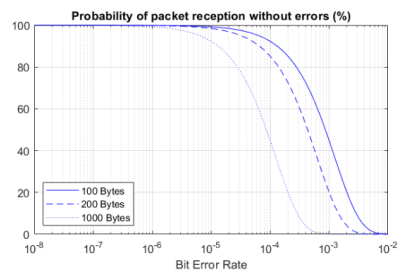

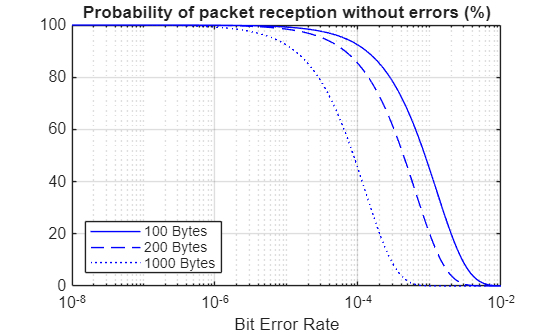

p = linspace(10^-8, 10^-2, 80000);

n1 = 100*8;
n2 = 200*8;
n10 = 1000*8;
i = 0;

C_nk1 = nchoosek(n1, i);
C_nk2 = nchoosek(n2, i);
C_nk10 = nchoosek(n10, i);

y = C_nk1 * p.^i .* (1-p).^(n1-i);
y1 = C_nk2 * p.^i .* (1-p).^(n2-i);
y2 = C_nk10 * p.^i .* (1-p).^(n10-i);

figure(3);
semilogx(p, y*100, 'b-')
hold on
semilogx(p, y1*100, 'b--')
hold on
semilogx(p, y2*100, 'b:')
hold off

grid on
xlabel('Bit Error Rate')
title('Probability of packet reception without errors (%)')
legend('100 Bytes', '200 Bytes', '1000 Bytes', 'Location', 'southwest')
xlim([10^-8, 10^-2]);

*2.e.*

Draw a plot using a logarithmic scale for the Y-axis (use the MATLAB function semilogy) with the same look as the plot below with the probability of a data frame being received without errors (for 𝑝 = 10−4 , 10−3 and 10−2 ) as a function of the packet size (all integer values from 64 Bytes up to 1518 Bytes). What do you conclude from these results? Answer:

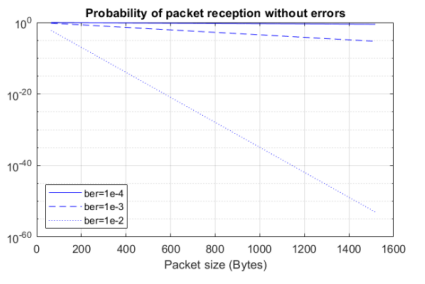

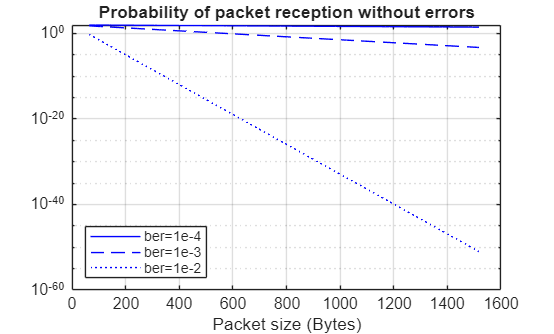

packet_sizes = 64:1518;

n = packet_sizes * 8;

p1 = 10^-4;
p2 = 10^-3;
p3 = 10^-2;

P_no_error_p1 = (1 - p1).^n;
P_no_error_p2 = (1 - p2).^n;
P_no_error_p3 = (1 - p3).^n;

figure;
semilogy(packet_sizes, P_no_error_p1 * 100, 'b-');
hold on;
semilogy(packet_sizes, P_no_error_p2 * 100, 'b--');
hold on;
semilogy(packet_sizes, P_no_error_p3 * 100, 'b:');
hold off;

grid on;
xlabel('Packet size (Bytes)');
title('Probability of packet reception without errors');
legend('ber=1e-4', 'ber=1e-3', 'ber=1e-2', 'Location', 'southwest');
xlim([0, 1600]);